# Exercise: Plot a Circle 

Create a local function in this live script named `plot_circle` that plots a circle centered at specified coordinates (x,y) with given radius (R ). The function should use MATLAB's `plot()` function for drawing the circle at the user-defined center point. 

Required function signature (interface): 

**Inputs:**

- `x` - X-coordinate of the circle's center (numeric scalar)

- `y` - Y-coordinate of the circle's center (numeric scalar)

- `r` - Radius of the circle (numeric scalar)

- n - Number of descrete points to use to approximate a circle (numeric scalar).  Default value of 10.

- `l_width` - Line width of the circle's rim (numeric).  Default value of 1.

Note that the first 3 input arguments are are required and the last 2 arguments are optional.  Use the [nargin ](https://www.mathworks.com/help/matlab/ref/nargin.html)capability to specify the behavior based on the number of arguments.  The documentation for nargin shows an example using the switch-case flow control.  You can equivalently use if-then-else.

**Return Variables: **None

**Implementation:**

The function should define the circle as a series of n points ( `n-1` straight line segments) with the vertices defined in polar coordinates:           

- Use theta (phase angle) values ranging from 0 to 2π to approximate the circle. 

- Compute the `x` and `y` coordinates of the circle-defining certices using the provided center and radius as in   $x_{circle} = R * cos(\theta) + x_{center}\\
y_{circle} = R * sin(\theta) + y_{center}\\$

The function should plot the circle's rim using the `plot` function.

**Example of using:**

This function call...

should generate an figure similar to this...

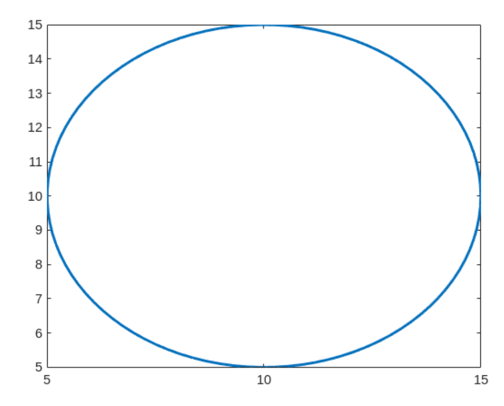

## Local Function

Define the function here...

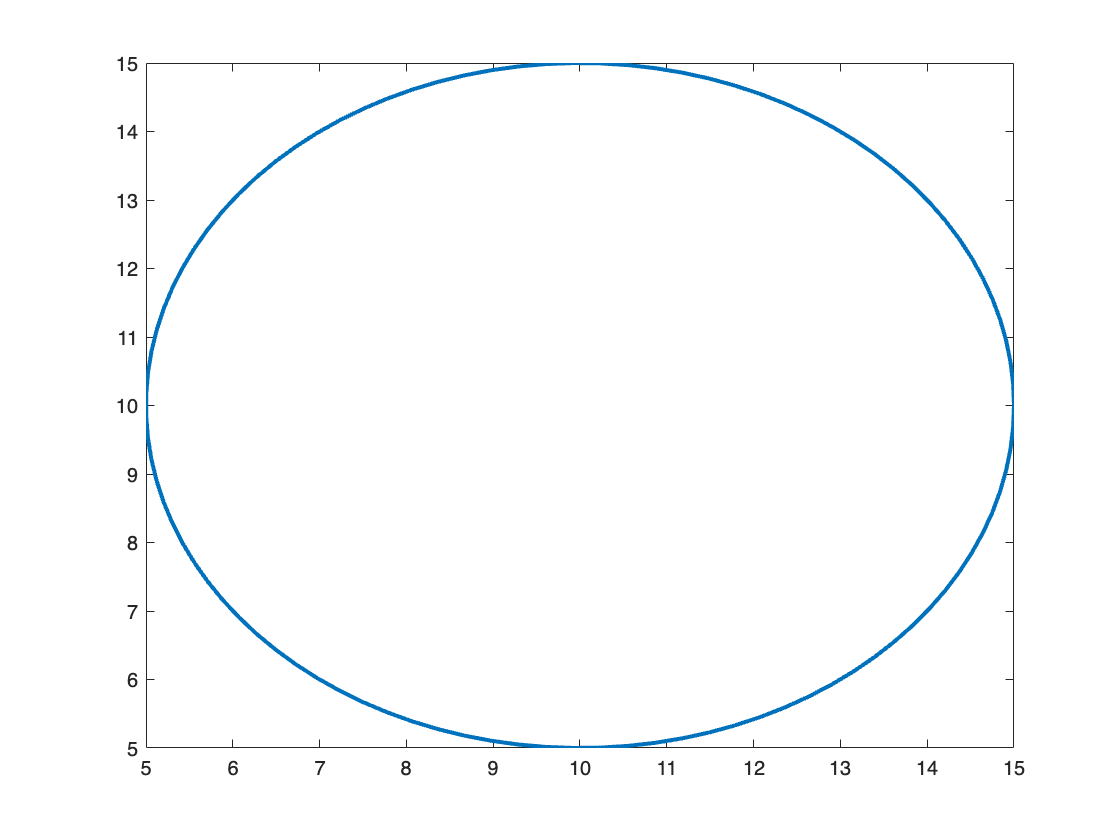

% Local function definition gotes here.
function plot_circle(x, y, r, n, l_width)
    if nargin < 5

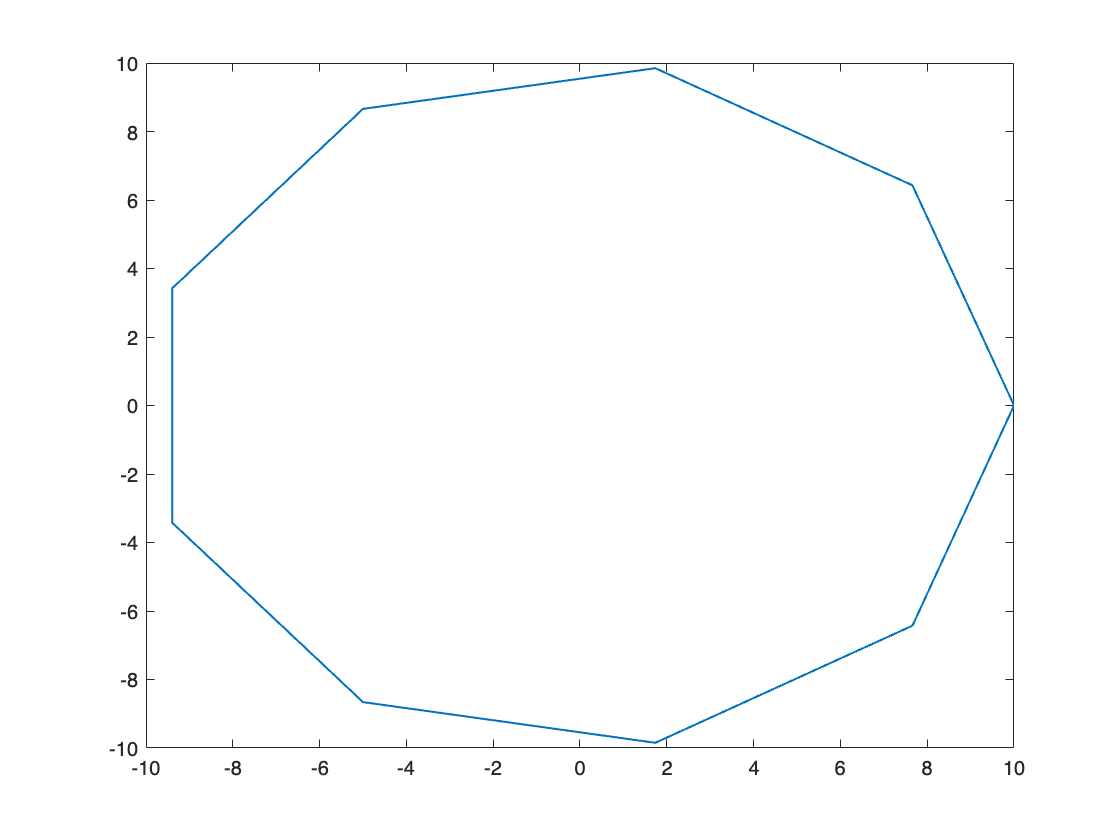

        l_width = 1;
    end
    if nargin < 4

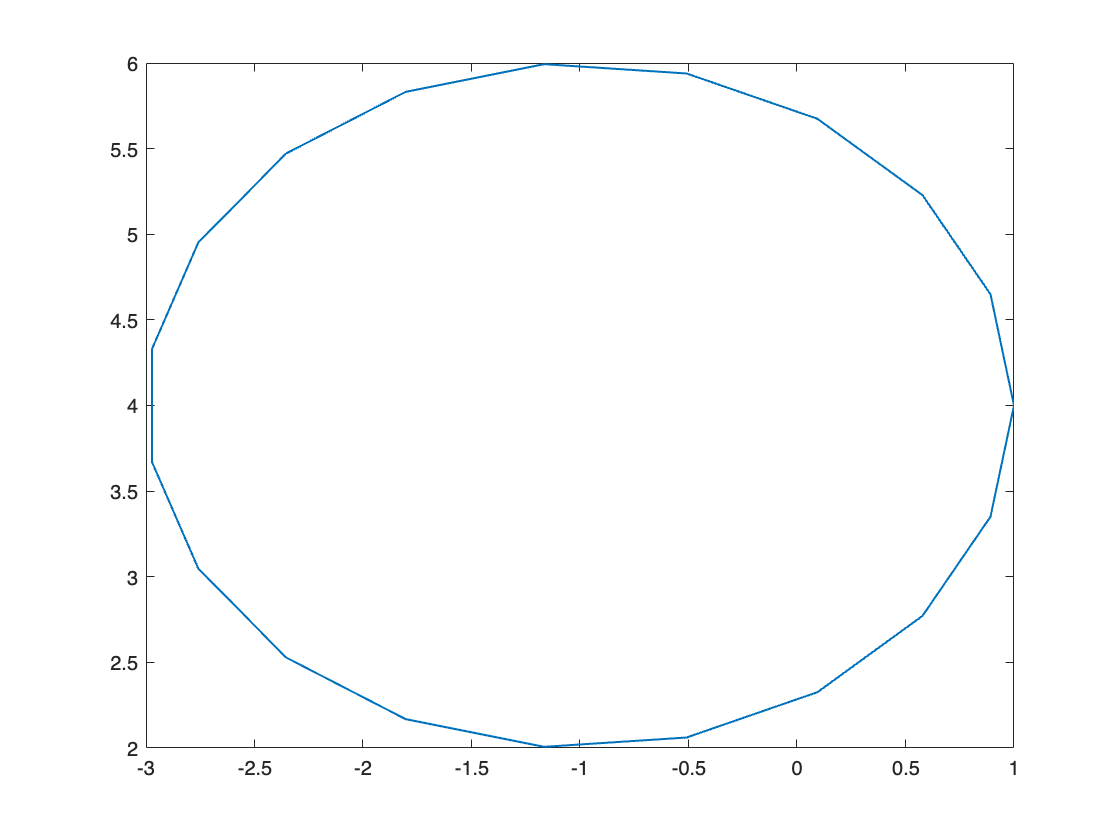

        n = 10;
    end
    theta = linspace(0, 2*pi, n);

    xx = r*cos(theta) + x;
    yy = r*sin(theta) + y;
    plot(xx, yy, 'LineWidth',l_width)
end

        

## Test / Demonstrate

Write at least three tests of your function.  The tests should verify that your function works as expected with 3, 4 or 5 input arguments. (Also good to experiment with how many line segments are required for the plot to look like a smooth circle.)

% Code to test your function goes here.

figure(1)
plot_circle(10, 10, 5, 100, 2);

figure(2)
plot_circle(0, 0, 10);

figure(3)
plot_circle(-1, 4, 2, 20)